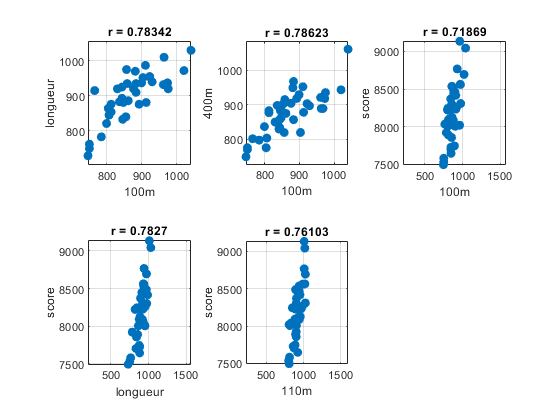

clear all;
close all;
clc;
load('Data_score.mat');
nameVariables = {'100m' ; 'longueur' ; 'poids' ; ...
'hauteur' ; '400m' ; '110m' ; 'disque' ; ...
'perche' ; 'javelot' ; '1500m' ; 'score'};

[totaux_tries, index]= sort(Data(:,11),'descend');
Donnees_decroissantes=Data(index, :); %permuter les lignes suivant le vecteur index

%indexSelectedPoints= setdiff(1:43, [42 43]);


%TEST ENLEVER LE 381 AU 1500m
indexSelectedPoints= setdiff(1:43, [38 42 43]);

Donnees_nettoyees = Donnees_decroissantes(indexSelectedPoints,:);
Donnees_centre_grav=mean(Donnees_nettoyees); %calcul du centre de gravité
Donnees_centrees=Donnees_nettoyees-Donnees_centre_grav; %tableau de données centrées
Donnees_variance=var(Donnees_centrees); %calcul des variances et écart-types des variables
Donnees_ecart_type=sqrt(Donnees_variance);
V=cov(Donnees_centrees); %matrices de covariance V
R=corr(Donnees_centrees); %matrice de corrélation R
Donnees_normalisees=Donnees_centrees./Donnees_ecart_type; % tableau de données centrées et réduites
plot_SignificantCorrelation(R, 0.7, Donnees_nettoyees, nameVariables, indexSelectedPoints, 1);

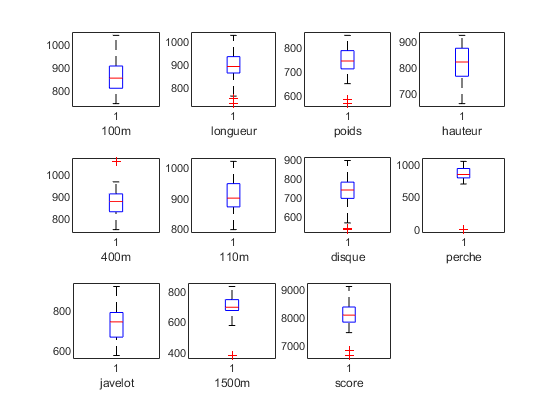

%dans perche/score : 2 athlètes qui ont eu un mauvais score les individus 8 et 15 : a enlever!
%correlation de 0,7 ici dans perche/score tire la droite!

figure(2);
for i=1:11
    subplot(3, 4, i);
    boxplot(Data(:,i)); %représentation synthétique des distributions de chaque variable séparément
    xlabel(nameVariables(i));
end

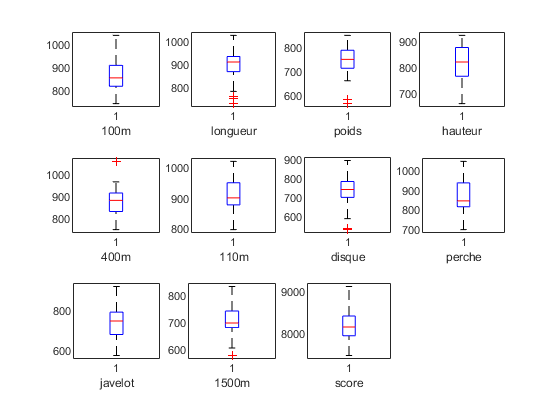

figure(3);
for i=1:11
    subplot(3, 4, i);
    boxplot(Donnees_nettoyees(:,i)); %représentation synthétique des distributions de chaque variable séparément
    xlabel(nameVariables(i));
end

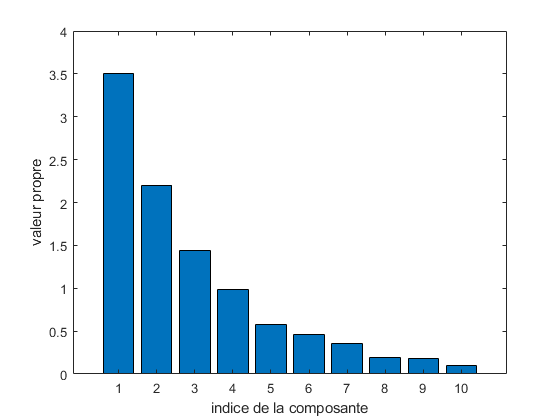

%ACP à partir des donnees centrees reduites
Donnees_nettoyees(:,11) = [];
Donnees_centre_grav=mean(Donnees_nettoyees); %calcul du centre de gravité
Donnees_centrees=Donnees_nettoyees-Donnees_centre_grav; %tableau de données centrées
Donnees_variance=var(Donnees_centrees); %calcul des variances et écart-types des variables
Donnees_ecart_type=sqrt(Donnees_variance);
V=cov(Donnees_centrees); %matrices de covariance V
R=corr(Donnees_centrees); %matrice de corrélation R
Donnees_normalisees=Donnees_centrees./Donnees_ecart_type; 
%calcul des axes principaux, facteurs principaux et composantes principales.
[vecteurs_propres,valeurs_propres]=eig(R);
[valeurs_propres,i]=sort(diag(valeurs_propres),'descend');
vecteurs_propres=vecteurs_propres(:, i);%vecteurs propres triés par ordre de valeur propre decroissante
sum(valeurs_propres); %somme valeurs propres égale à la trace = 10
composantes_principales=Donnees_normalisees*vecteurs_propres;
vecteurs_propres'*vecteurs_propres; %=identité donc ok avec propriétés des axes principaux (et des facteurs principaux car f=Ma, et M=I)
W=eye(size(Donnees_normalisees,1))/size(Donnees_normalisees,1);
composantes_principales'*W*composantes_principales; %= matrice diagonale avec vecteurs propres.
figure
bar(valeurs_propres)
xlabel('indice de la composante');
ylabel('valeur propre');

sum(valeurs_propres(1:4))/sum(valeurs_propres(:)); %qualité globale des 4
sum(valeurs_propres(1))/sum(valeurs_propres(:)); %qualité globale du premier 
correlationCircle=corr(Donnees_normalisees,composantes_principales);

correlationCircle =     0.8888    0.0726   -0.2074   -0.2480    0.1147    0.0909   -0.0974    0.1376   -0.0109   -0.2241
    0.8723   -0.0392    0.0780   -0.1137   -0.0259    0.3766    0.1686    0.1376   -0.0596    0.1586
    0.2062   -0.8455   -0.2352    0.0797    0.0113   -0.1944    0.3107   -0.0411   -0.2069   -0.0444
    0.2899   -0.2387    0.7806    0.1714   -0.4314    0.1259    0.0109   -0.0933    0.0063   -0.0968
    0.8411    0.3408   -0.1190   -0.0791    0.1577    0.0342   -0.0205   -0.3582   -0.0265    0.0208
    0.8243   -0.1183   -0.0304   -0.0054   -0.2453   -0.3760   -0.2927    0.0715   -0.0598    0.0984
    0.1144   -0.8300   -0.2925   -0.3278   -0.1163    0.0422   -0.0021   -0.0617    0.2921    0.0220
    0.2685   -0.2070    0.7681   -0.1679    0.4540   -0.2177    0.0637    0.0414    0.0844    0.0204
    0.1434   -0.6004   -0.0612    0.6676    0.2690    0.1929   -0.2446   -0.0026    0.0069    0.0063
    0.5787    0.4502   -0.1734    0.5379   -0.0591   -0.1701    0.2574 

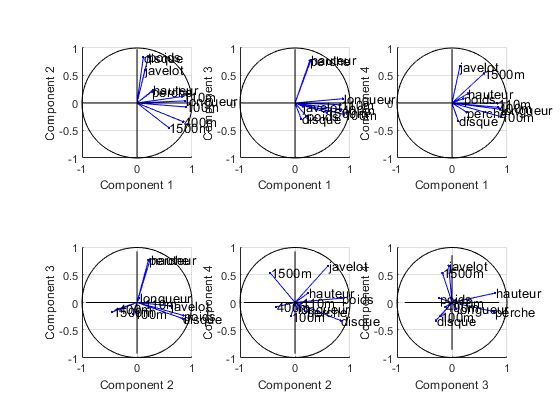

%correlationCircle=sqrt(valeurs_propres').*vecteurs_propres
plot_CorrelationCircle(correlationCircle, nameVariables(1:10), 4, 6)